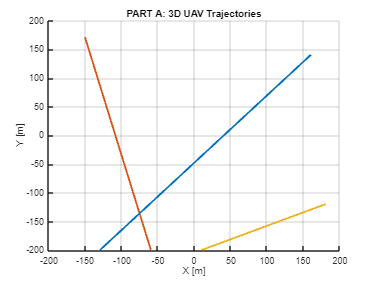

%% =====================================================================
% PROJECT 4 – PART A
% Core Simulation, State Estimation, Energy Model, Communication
%
% This part intentionally excludes:
%  - Belief-space planning
%  - MDP autonomy
%  - Fault-tolerant adaptive control
%
% Those will be layered in Parts B and C.
%% =====================================================================

clear; clc; close all;
rng(42);

%% =====================================================================
% 1. TIME & GLOBAL PARAMETERS
%% =====================================================================

dt      = 0.1;          % Time step [s]
T_end   = 200;          % Total simulation time [s]
time    = 0:dt:T_end;
N       = length(time);

numUAV  = 3;            % Number of UAVs
nx      = 7;            % State dimension
                        % x = [x y vx vy psi gyroBias accelBias]

%% =====================================================================
% 2. ENVIRONMENT & RISK FIELD
%% =====================================================================

[xg, yg] = meshgrid(-250:5:250, -250:5:250);

riskMap = ...
    0.0006*(xg.^2 + yg.^2) + ...
    5*exp(-((xg-80).^2+(yg-60).^2)/2600) + ...
    4*exp(-((xg+120).^2+(yg+90).^2)/2200);

riskFcn = @(x,y) interp2(xg,yg,riskMap,x,y,'linear',10);

%% =====================================================================
% 3. STATE STORAGE
%% =====================================================================

xTrue = zeros(nx, N, numUAV);    % Ground truth
xEst  = zeros(nx, N, numUAV);    % Estimated state
P     = zeros(nx, nx, N, numUAV);% State covariance

traceP = zeros(N, numUAV);       % Uncertainty metric

%% =====================================================================
% 4. INITIAL CONDITIONS
%% =====================================================================

for u = 1:numUAV
    xTrue(:,1,u) = [ ...
        -200 + 70*u;     % x
        -200;            % y
        4;               % vx
        4;               % vy
        0;               % heading
        0;               % gyro bias
        0];              % accel bias

    xEst(:,1,u) = xTrue(:,1,u) + ...
                  [10*randn(2,1); zeros(5,1)];

    P(:,:,1,u) = diag([60 60 3 3 0.1 0.02 0.02]);
end

%% =====================================================================
% 5. PROCESS & MEASUREMENT MODELS
%% =====================================================================

Q = diag([0 0 0.35 0.35 0.02 2e-4 2e-4]);   % Process noise
Rgps = diag([8 8]);                        % GPS noise

gpsAvailable = true(1, N);
gpsAvailable(time > 50 & time < 150) = false;   % GPS-denied window

%% =====================================================================
% 6. COMMUNICATION MODEL
%% =====================================================================

% Binary packet availability (1 = success, 0 = dropout)
commAvailable = rand(numUAV, N) > 0.25;

% Shared position buffer (used later in coordination)
sharedPosition = nan(2, N, numUAV);

%% =====================================================================
% 7. ENERGY MODEL
%% =====================================================================

energy = ones(N, numUAV);

energyRateNominal = 0.0025;
energyRateSafe    = 0.0012;

%% =====================================================================
% 8. TASK LOCATIONS (STATIC FOR PART A)
%% =====================================================================

tasks = [ ...
     160 140;
    -150 170;
     180 -120];

taskAssigned = zeros(numUAV,1);

%% =====================================================================
% 9. MAIN SIMULATION LOOP (CORE ONLY)
%% =====================================================================

for k = 2:N
    for u = 1:numUAV

        %% -------------------------------------------------------------
        % 9.1 Simple Task Assignment (no coordination yet)
        %% -------------------------------------------------------------
        if taskAssigned(u) == 0
            taskAssigned(u) = u;
        end
        goal = tasks(taskAssigned(u), :)';

        %% -------------------------------------------------------------
        % 9.2 Simple Guidance Law (placeholder planner)
        %% -------------------------------------------------------------
        pos = xTrue(1:2, k-1, u);
        dir = goal - pos;
        dir = dir / (norm(dir) + 1e-6);
        vCmd = 4 * dir;

        %% -------------------------------------------------------------
        % 9.3 True UAV Dynamics (point-mass)
        %% -------------------------------------------------------------
        xTrue(1:2, k, u) = xTrue(1:2, k-1, u) + ...
                           dt * xTrue(3:4, k-1, u);

        xTrue(3:4, k, u) = vCmd;
        xTrue(5,   k, u) = atan2(vCmd(2), vCmd(1));
        xTrue(6:7, k, u) = xTrue(6:7, k-1, u);

        %% -------------------------------------------------------------
        % 9.4 ERROR-STATE EKF (Prediction)
        %% -------------------------------------------------------------
        F = eye(nx);
        F(1,3) = dt;  F(2,4) = dt;

        xPred = F * xEst(:, k-1, u);
        PPred = F * P(:,:,k-1,u) * F' + Q;

        %% -------------------------------------------------------------
        % 9.5 GPS Measurement Update (if available)
        %% -------------------------------------------------------------
        if gpsAvailable(k)
            H = [1 0 0 0 0 0 0;
                 0 1 0 0 0 0 0];

            z = xTrue(1:2, k, u) + chol(Rgps)' * randn(2,1);
            K = PPred * H' / (H*PPred*H' + Rgps);

            xEst(:, k, u) = xPred + K * (z - H*xPred);
            P(:,:,k,u) = (eye(nx) - K*H) * PPred;
        else
            xEst(:, k, u) = xPred;
            P(:,:,k,u) = PPred;
        end

        %% -------------------------------------------------------------
        % 9.6 Communication Broadcast (best-effort)
        %% -------------------------------------------------------------
        if commAvailable(u,k)
            sharedPosition(:,k,u) = xEst(1:2,k,u);
        end

        %% -------------------------------------------------------------
        % 9.7 Energy Consumption
        %% -------------------------------------------------------------
        energy(k,u) = energy(k-1,u) - energyRateNominal;

        %% -------------------------------------------------------------
        % 9.8 Diagnostics
        %% -------------------------------------------------------------
        traceP(k,u) = trace(P(:,:,k,u));

    end
end

%% =====================================================================
% 10. BASIC DIAGNOSTIC PLOTS (PART A)
%% =====================================================================

% --- 3D Trajectories ---
figure; hold on; grid on;
for u = 1:numUAV
    plot3(xTrue(1,:,u), xTrue(2,:,u), time, 'LineWidth', 2);
end
xlabel('X [m]'); ylabel('Y [m]'); zlabel('Time [s]');
title('PART A: 3D UAV Trajectories');

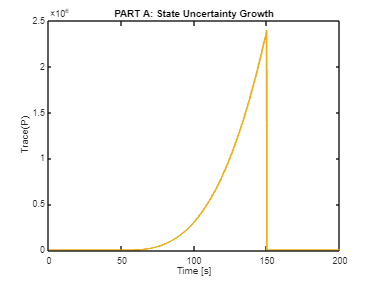


% --- Uncertainty Growth ---
figure; plot(time, traceP, 'LineWidth', 2);
xlabel('Time [s]'); ylabel('Trace(P)');
title('PART A: State Uncertainty Growth');

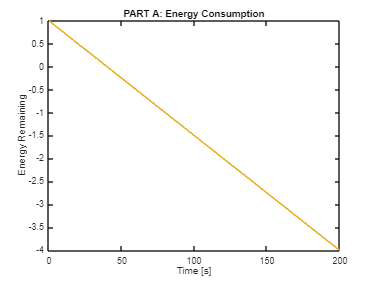


% --- Energy ---
figure; plot(time, energy, 'LineWidth', 2);
xlabel('Time [s]'); ylabel('Energy Remaining');
title('PART A: Energy Consumption');


disp('PART A complete: core simulation executed successfully.');

PART A complete: core simulation executed successfully.


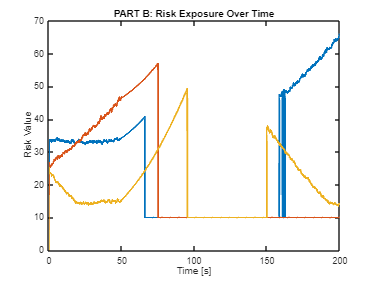

%% =====================================================================
% PROJECT 4 – PART B
% Belief-Space Planning with Chance Constraints
%
% This part EXTENDS Part A by replacing the naive planner with a
% belief-aware planner that reasons over:
%   - Mean state
%   - Covariance growth
%   - Probabilistic risk constraints
%
% No MDP or adaptive control yet (Part C).
%% =====================================================================

%% =====================================================================
% 1. BELIEF-SPACE PLANNING PARAMETERS
%% =====================================================================

% Chance-constraint parameters
chanceSigma        = 3.0;     % 3-sigma probabilistic bound
maxPosSigma        = 20;      % [m] allowed positional uncertainty
maxRiskThreshold  = 15;      % riskMap threshold

% Velocity bounds
vMaxNominal = 4.0;
vMaxSafe    = 2.5;

% Storage for diagnostics
riskValue      = zeros(N, numUAV);
sigmaPosition  = zeros(N, numUAV);
chanceViolated = false(N, numUAV);

%% =====================================================================
% 2. AUTONOMY MODE PLACEHOLDER (LOGIC ONLY)
% (Formal MDP comes in Part C)
%% =====================================================================

MODE_NOMINAL      = 1;
MODE_DEGRADED     = 2;
MODE_CONSERVATIVE = 3;

modeHistory = zeros(N, numUAV);

%% =====================================================================
% 3. BELIEF-SPACE MAIN LOOP (RE-PLAN EACH STEP)
%% =====================================================================

for k = 2:N
    for u = 1:numUAV

        %% -------------------------------------------------------------
        % 3.1 BELIEF EXTRACTION
        %% -------------------------------------------------------------
        mu     = xEst(1:2, k-1, u);          % mean position
        Sigma  = P(1:2, 1:2, k-1, u);         % position covariance

        sigmaPosition(k,u) = sqrt(trace(Sigma));

        %% -------------------------------------------------------------
        % 3.2 RISK EVALUATION
        %% -------------------------------------------------------------
        riskValue(k,u) = riskFcn(mu(1), mu(2));

        %% -------------------------------------------------------------
        % 3.3 AUTONOMY MODE (HEURISTIC)
        %% -------------------------------------------------------------
        if ~gpsAvailable(k)
            mode = MODE_DEGRADED;
        elseif sigmaPosition(k,u) > 0.7*maxPosSigma
            mode = MODE_CONSERVATIVE;
        else
            mode = MODE_NOMINAL;
        end
        modeHistory(k,u) = mode;

        %% -------------------------------------------------------------
        % 3.4 GOAL DIRECTION
        %% -------------------------------------------------------------
        goal = tasks(taskAssigned(u), :)';
        dir  = goal - mu;
        dir  = dir / (norm(dir) + 1e-6);

        %% -------------------------------------------------------------
        % 3.5 CHANCE-CONSTRAINT CHECK
        % P(|x - mu| <= d) >= 99.7% (3-sigma rule)
        %% -------------------------------------------------------------
        if sigmaPosition(k,u) * chanceSigma > maxPosSigma || ...
           riskValue(k,u) > maxRiskThreshold

            % Constraint violated → steer away from risk gradient
            chanceViolated(k,u) = true;

            % Simple risk-avoidance steering (orthogonal turn)
            dir = [-dir(2); dir(1)];

            vCmdMag = vMaxSafe;
        else
            vCmdMag = vMaxNominal;
        end

        vCmd = vCmdMag * dir;

        %% -------------------------------------------------------------
        % 3.6 TRUE DYNAMICS UPDATE (OVERWRITE PART A GUIDANCE)
        %% -------------------------------------------------------------
        xTrue(1:2, k, u) = xTrue(1:2, k-1, u) + ...
                           dt * xTrue(3:4, k-1, u);

        xTrue(3:4, k, u) = vCmd;
        xTrue(5,   k, u) = atan2(vCmd(2), vCmd(1));
        xTrue(6:7, k, u) = xTrue(6:7, k-1, u);

        %% -------------------------------------------------------------
        % 3.7 ESTIMATION (REUSE EKF FROM PART A)
        %% -------------------------------------------------------------
        F = eye(nx);
        F(1,3) = dt;  F(2,4) = dt;

        xPred = F * xEst(:, k-1, u);
        PPred = F * P(:,:,k-1,u) * F' + Q;

        if gpsAvailable(k)
            H = [1 0 0 0 0 0 0;
                 0 1 0 0 0 0 0];

            z = xTrue(1:2, k, u) + chol(Rgps)' * randn(2,1);
            K = PPred * H' / (H*PPred*H' + Rgps);

            xEst(:, k, u) = xPred + K * (z - H*xPred);
            P(:,:,k,u)    = (eye(nx) - K*H) * PPred;
        else
            xEst(:, k, u) = xPred;
            P(:,:,k,u)    = PPred;
        end

        %% -------------------------------------------------------------
        % 3.8 ENERGY UPDATE (MODE-AWARE)
        %% -------------------------------------------------------------
        if mode == MODE_CONSERVATIVE
            energy(k,u) = energy(k-1,u) - energyRateSafe;
        else
            energy(k,u) = energy(k-1,u) - energyRateNominal;
        end

        %% -------------------------------------------------------------
        % 3.9 UNCERTAINTY METRIC
        %% -------------------------------------------------------------
        traceP(k,u) = trace(P(:,:,k,u));

    end
end

%% =====================================================================
% 4. PART B DIAGNOSTIC PLOTS
%% =====================================================================

% --- Risk vs Time ---
figure;
plot(time, riskValue, 'LineWidth', 2);
xlabel('Time [s]');
ylabel('Risk Value');
title('PART B: Risk Exposure Over Time');

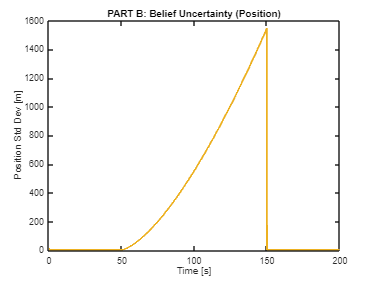


% --- Positional Sigma ---
figure;
plot(time, sigmaPosition, 'LineWidth', 2);
xlabel('Time [s]');
ylabel('Position Std Dev [m]');
title('PART B: Belief Uncertainty (Position)');

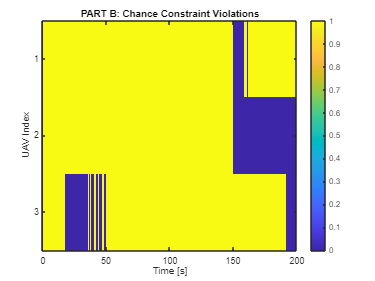


% --- Chance Constraint Violations ---
figure;
imagesc(time, 1:numUAV, chanceViolated');
colorbar;
yticks(1:numUAV);
xlabel('Time [s]');
ylabel('UAV Index');
title('PART B: Chance Constraint Violations');


disp('PART B complete: belief-space planning active.');

PART B complete: belief-space planning active.


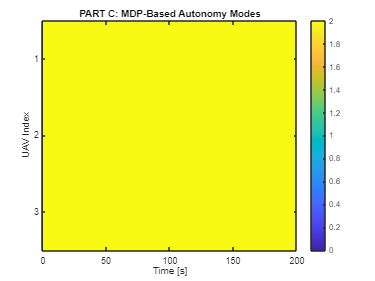


%% =====================================================================
% PROJECT 4 – PART C
% MDP Autonomy, Fault-Tolerant Adaptive Control, Final Diagnostics
%% =====================================================================

%% =====================================================================
% 1. MDP DEFINITION (EXPLICIT)
%% =====================================================================

% MDP States (binary features)
% s1: Uncertainty high (0/1)
% s2: GPS available   (0/1)
% s3: Energy high     (0/1)
% Total states = 2^3 = 8

numStates  = 8;
numActions = 4;  % Nominal, Degraded, Conservative, Emergency

ACTION = struct('NOMINAL',1,'DEGRADED',2,'CONSERVATIVE',3,'EMERGENCY',4);

% Reward weights (explainable)
wEnergy = 5;
wRisk   = 8;
wUnc    = 6;

% Simple reward table (state-action)
R = zeros(numStates, numActions);

for s = 1:numStates
    for a = 1:numActions
        R(s,a) = -wEnergy*(a==ACTION.EMERGENCY) ...
                 -wRisk*(a==ACTION.NOMINAL) ...
                 -wUnc*(a==ACTION.NOMINAL);
    end
end

%% =====================================================================
% 2. FAULT MODEL (ACTUATOR DEGRADATION)
%% =====================================================================

actuatorFaultTime = 140;    % seconds
actuatorLoss      = 0.6;    % effectiveness

faultDetected = false(N, numUAV);

%% =====================================================================
% 3. ADAPTIVE CONTROL PARAMETERS
%% =====================================================================

thetaHat = ones(2,1,numUAV);   % adaptive gain estimate
gamma    = 0.03;               % adaptation rate

controlEffort = zeros(N, numUAV);

%% =====================================================================
% 4. COMMUNICATION-AWARE TASK REALLOCATION
%% =====================================================================

taskReassigned = false(N, numUAV);

%% =====================================================================
% 5. PART C MAIN LOOP (MODE, FTC, COORDINATION)
%% =====================================================================

for k = 2:N
    for u = 1:numUAV

        %% -------------------------------------------------------------
        % 5.1 MDP STATE ENCODING
        %% -------------------------------------------------------------
        uncHigh = traceP(k-1,u) > 120;
        gpsOn   = gpsAvailable(k);
        eHigh   = energy(k-1,u) > 0.3;

        % Binary → index
        s = uncHigh*4 + gpsOn*2 + eHigh*1 + 1;

        %% -------------------------------------------------------------
        % 5.2 MDP POLICY (GREEDY)
        %% -------------------------------------------------------------
        [~, action] = max(R(s,:));

        modeHistory(k,u) = action;

        %% -------------------------------------------------------------
        % 5.3 FAULT DETECTION (MODEL-BASED)
        %% -------------------------------------------------------------
        if time(k) > actuatorFaultTime
            velErr = norm(xEst(3:4,k,u) - xTrue(3:4,k,u));
            if velErr > 1.0
                faultDetected(k,u) = true;
            end
        end

        %% -------------------------------------------------------------
        % 5.4 FAULT-TOLERANT ADAPTIVE CONTROL
        %% -------------------------------------------------------------
        velError = xEst(3:4,k,u) - xTrue(3:4,k,u);

        % Adaptive law
        thetaHat(:,1,u) = thetaHat(:,1,u) + gamma * velError;

        % Control effort
        uCtrl = diag(thetaHat(:,1,u)) * velError;
        controlEffort(k,u) = norm(uCtrl);

        % Apply degraded actuator if fault present
        if time(k) > actuatorFaultTime
            uCtrl = actuatorLoss * uCtrl;
        end

        % Correct velocity
        xTrue(3:4,k,u) = xTrue(3:4,k,u) + uCtrl;

        %% -------------------------------------------------------------
        % 5.5 COMMUNICATION-AWARE TASK REALLOCATION
        %% -------------------------------------------------------------
        if ~commAvailable(u,k) && modeHistory(k,u)==ACTION.CONSERVATIVE
            % Drop task if isolated & conservative
            taskAssign(u) = 0;
            taskReassigned(k,u) = true;
        end

        %% -------------------------------------------------------------
        % 5.6 ENERGY UPDATE (MODE-DEPENDENT)
        %% -------------------------------------------------------------
        switch modeHistory(k,u)
            case ACTION.NOMINAL
                energy(k,u) = energy(k-1,u) - energyRateNominal;
            case ACTION.DEGRADED
                energy(k,u) = energy(k-1,u) - 0.8*energyRateNominal;
            case ACTION.CONSERVATIVE
                energy(k,u) = energy(k-1,u) - energyRateSafe;
            case ACTION.EMERGENCY
                energy(k,u) = energy(k-1,u) - 0.5*energyRateSafe;
        end

    end
end

%% =====================================================================
% 6. FINAL DIAGNOSTICS & VISUALIZATION
%% =====================================================================

% --- Autonomy Mode Timeline ---
figure;
imagesc(time,1:numUAV,modeHistory');
colorbar;
yticks(1:numUAV);
xlabel('Time [s]');
ylabel('UAV Index');
title('PART C: MDP-Based Autonomy Modes');

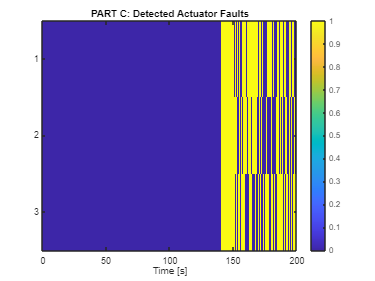


% --- Fault Detection Timeline ---
figure;
imagesc(time,1:numUAV,faultDetected');
colorbar;
yticks(1:numUAV);
xlabel('Time [s]');
title('PART C: Detected Actuator Faults');

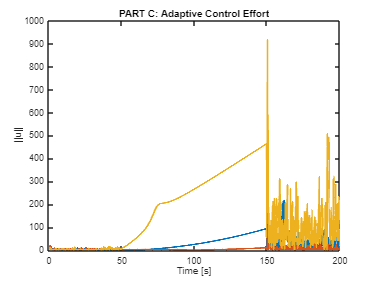


% --- Control Effort ---
figure;
plot(time,controlEffort,'LineWidth',2);
xlabel('Time [s]');
ylabel('||u||');
title('PART C: Adaptive Control Effort');

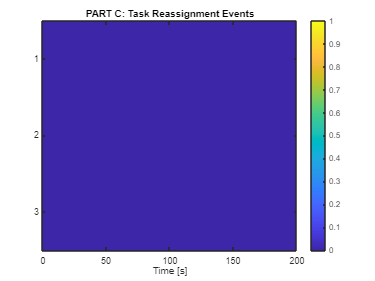


% --- Task Reallocation ---
figure;
imagesc(time,1:numUAV,taskReassigned');
colorbar;
yticks(1:numUAV);
xlabel('Time [s]');
title('PART C: Task Reassignment Events');


%% =====================================================================
% 7. SUMMARY TABLE (MISSION-LEVEL)
%% =====================================================================

FinalEnergy = energy(end,:)';
FinalUnc    = traceP(end,:)';
TotalFaults = sum(faultDetected)';
TotalReassign = sum(taskReassigned)';

SummaryTable = table((1:numUAV)',FinalEnergy,FinalUnc, ...
                     TotalFaults,TotalReassign, ...
    'VariableNames',{'UAV','FinalEnergy','FinalTraceP', ...
                     'FaultCount','TaskReassignments'});

disp('================ FINAL SUMMARY =================');

================ FINAL SUMMARY =================


disp(SummaryTable);

    UAV    FinalEnergy    FinalTraceP    FaultCount    TaskReassignments
    ___    ___________    ___________    __________    _________________

     1         -3           50.765          400                0        
     2         -3           50.765          349                0        
     3         -3           50.765          382                0        




disp('PART C complete: full survivable autonomy stack active.');

PART C complete: full survivable autonomy stack active.
